## MATLABチュートリアル

MATLAB （日本語では「マトラボ」，あるいは「マトラブ」と発声されることが多い）は反復的な分析と設計プロセスに適したデスクトップ環境と，行列と配列を直接表現できるプログラミング言語が 1 つに組み合わさった技術計算言語の一種です．

MATLABではツールボックスと呼ばれる様々なライブラリを駆使することで，複雑な数値計算を容易に実行することができます．

ここではMATLABの基本的な文法・ツールについて解説します．

### MATLAB Live Editor について

MATLAB Live Editor とはライブエディターと呼ばれる形式で作成したプログラムの実行と実行結果を記録しながらデータ分析を進めるツールです．この本文のようにWord形式のセルとMATLABのコードを同居させることができるので，勉強用に技術ノートなり解説なりを作ることが可能です．

また，C言語の授業で扱ったBCPADのように「実行」を押すだけでプログラムを実行できます. 皆さんが卒業研究でやるようなシミュレーションには不向きですが, プログラミングに慣れるためにはちょうどいいツールです.

MATLAB Live Editor が嫌になったらその辺の院生（か先生）に声をかけてください．より良いエディタを紹介します．

### MATLAB Live Editor の基本的な使い方

ここでは画面出力「disp」を用いた文字列の表示を例に挙げ，MATLAB Live Editor の基本的な使い方を説明します．

#### 1．MATLAB Live Editor の起動

    Windows バーの左下の検索欄で「matlab」と入力して，候補で現れるMATLABを起動する．

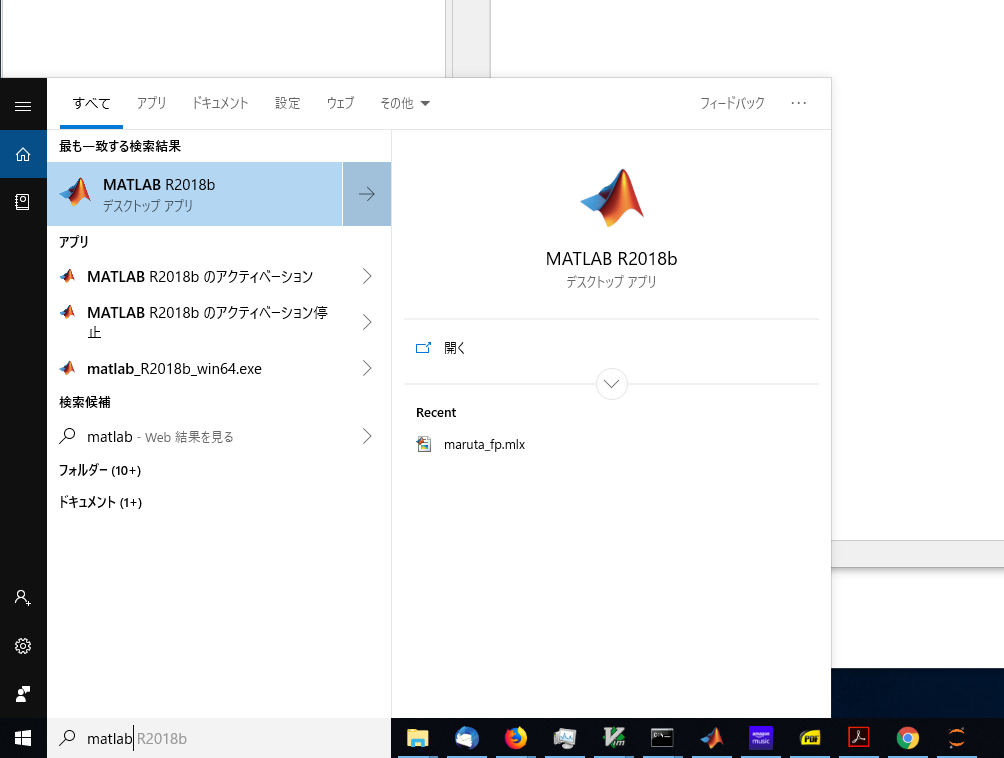

    スプラッシュ画面が表示されたあと，しばらくするとこのような画面が立ち上がります．これで起動完了です．

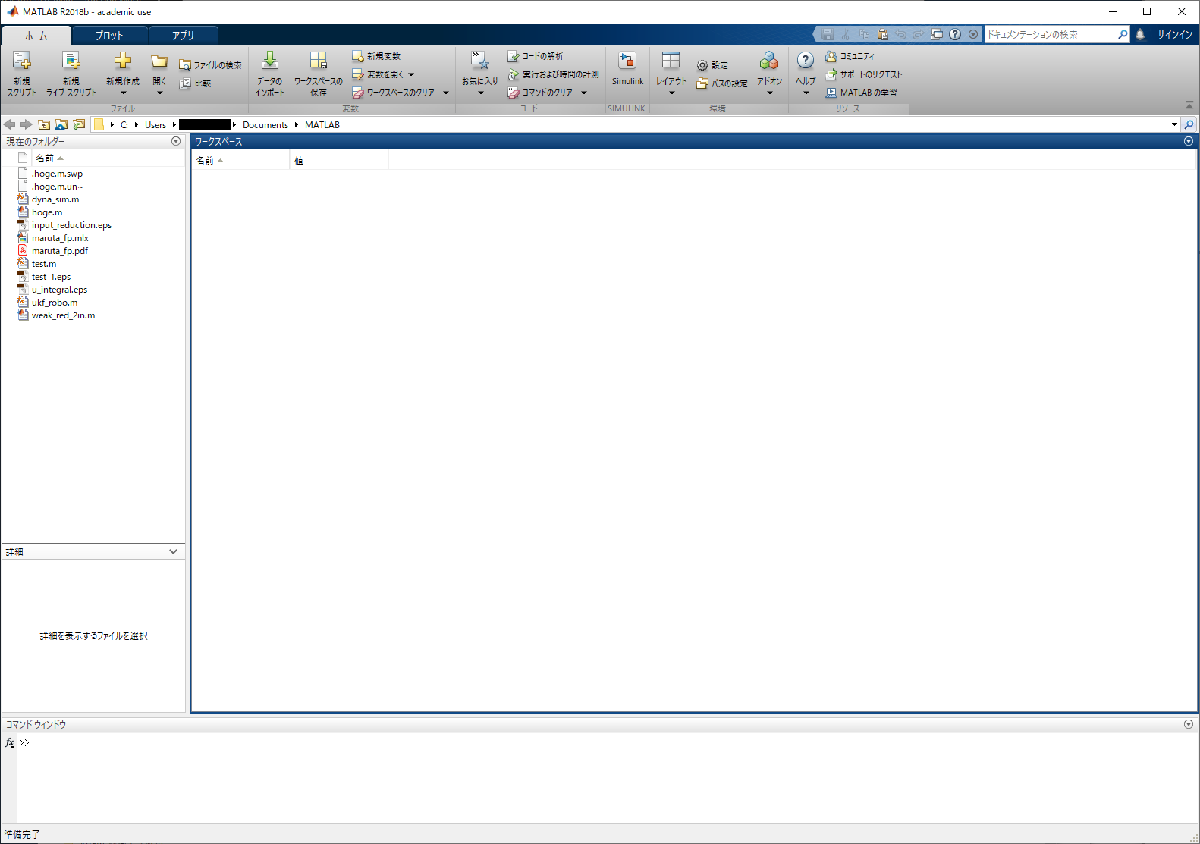

### 2． 新しいLive Script ファイルの作成

    まず以下の流れに沿って，新しいファイルを作りたいディレクトリに移動します. 

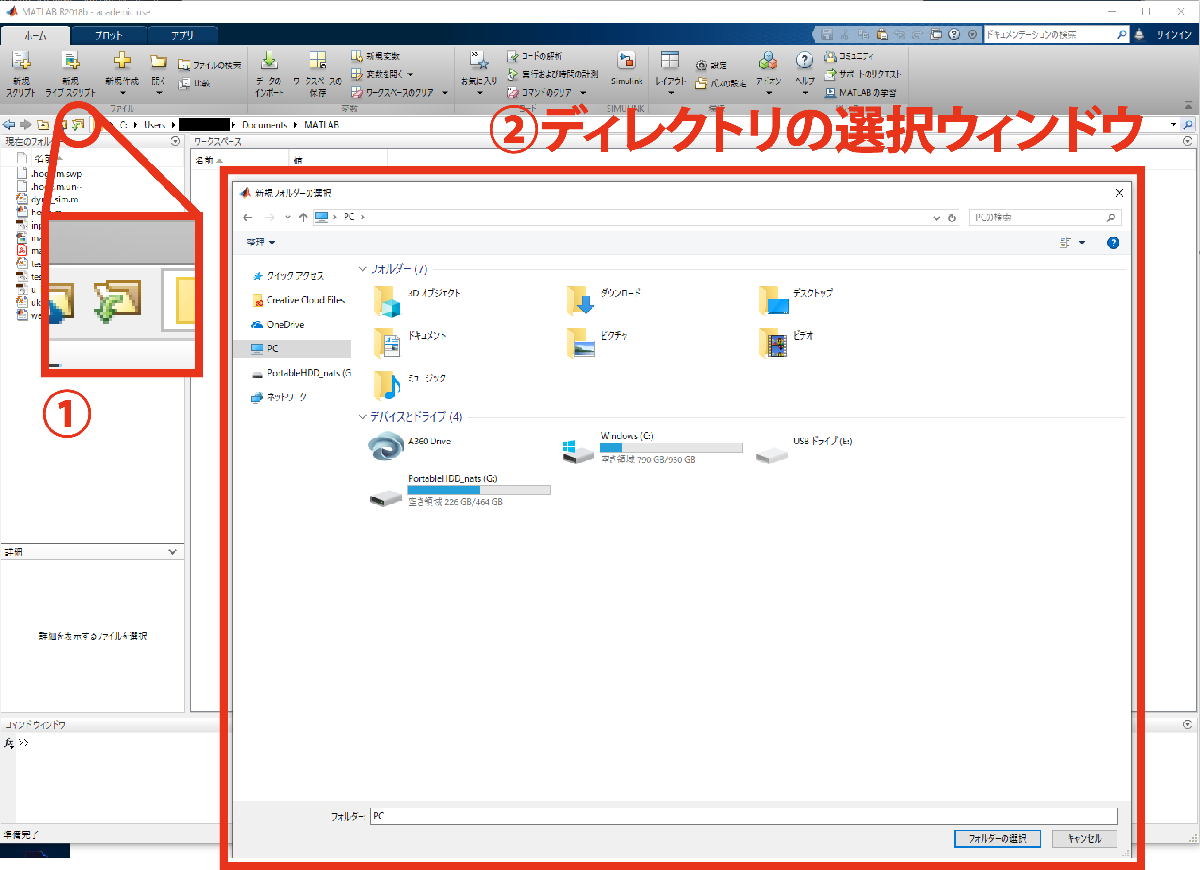

    その後メニューバーの「ホーム」をクリックし，「新規ライブスクリプト」をを選択します．

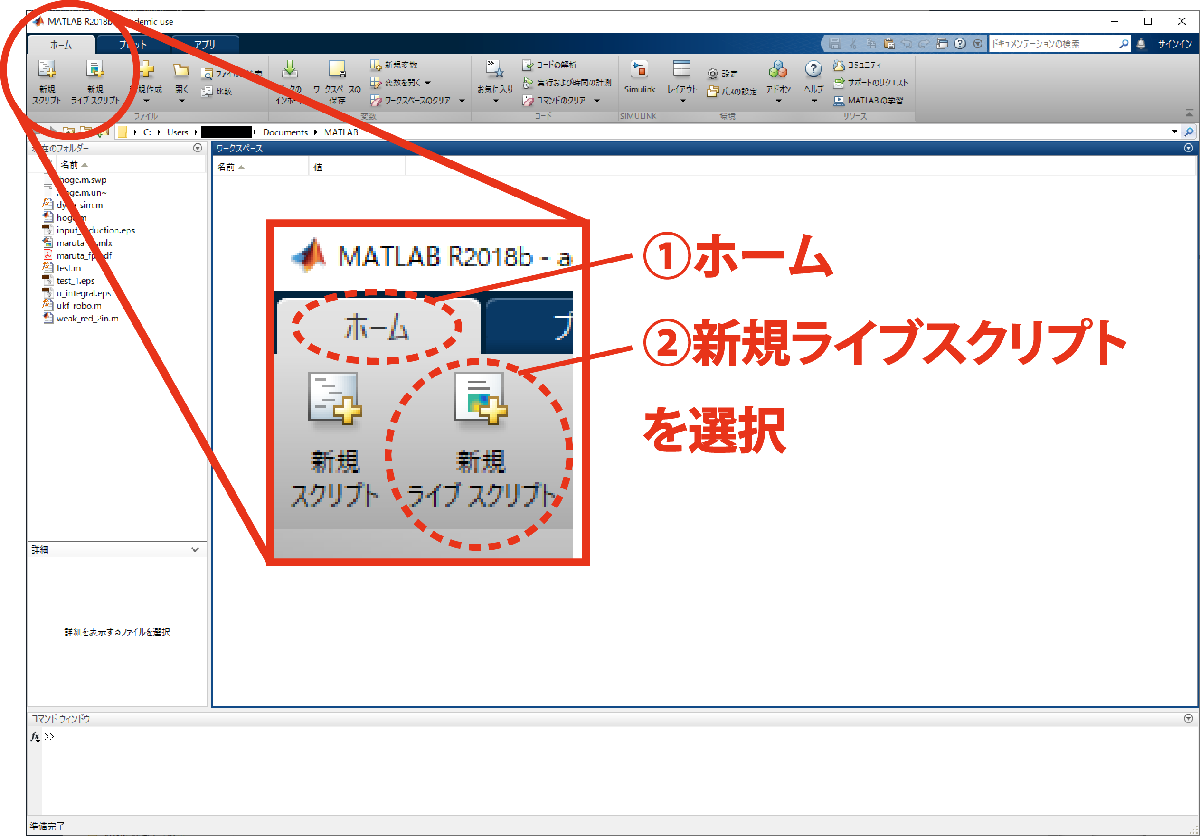

### 3.  準備完了

    MATLABを起動し，ライブスクリプトファイルを作ることができました．これで準備完了です．

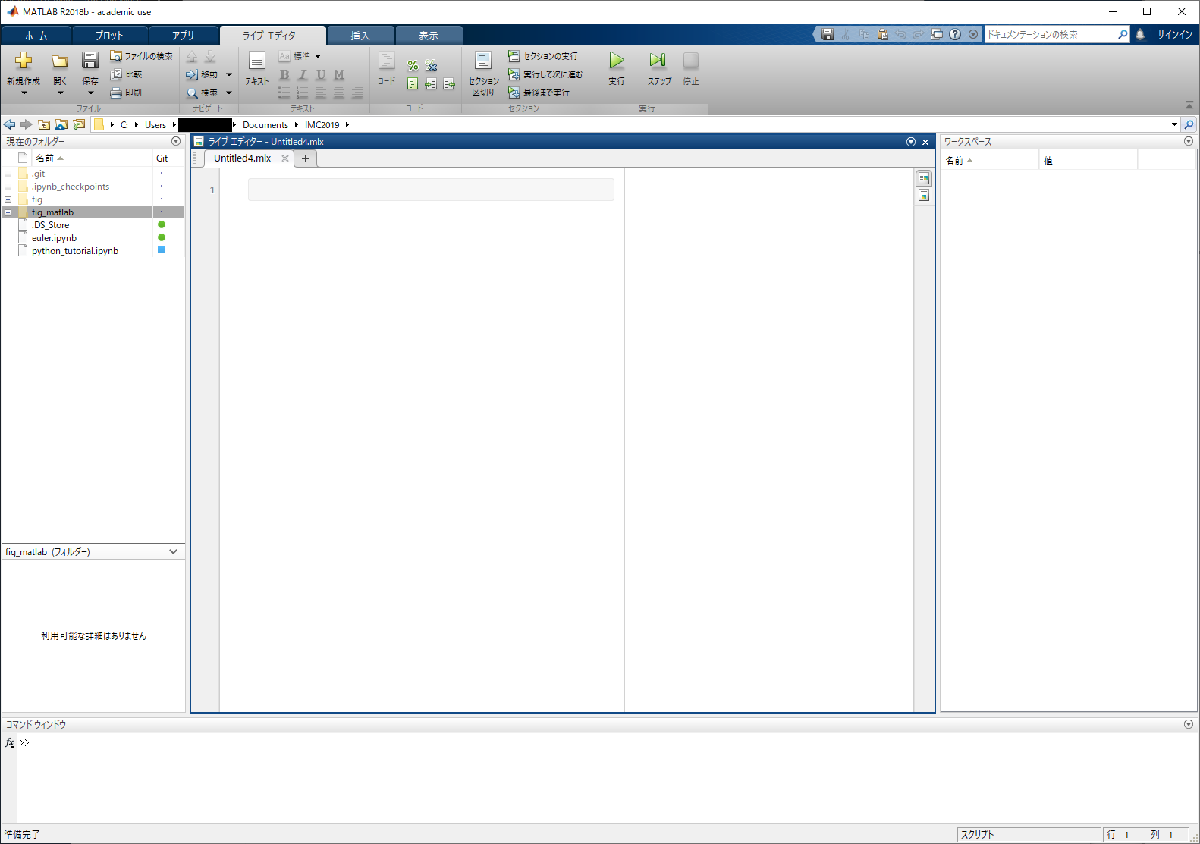

### 4. 実行

    「disp」とは(後にも出てきますが)変数などを表示するための関数です．これを使って制御システム研究室のコアタイムを表示しましょう．まずセルのステータスが「コード」になっていることを確認し，下図のように「disp`('コアタイムは10時30分～18時です')」`と入力してください．その後「実行」を押すとセルのプログラムが実行され実行結果がセルの右（か下）に表示されます．

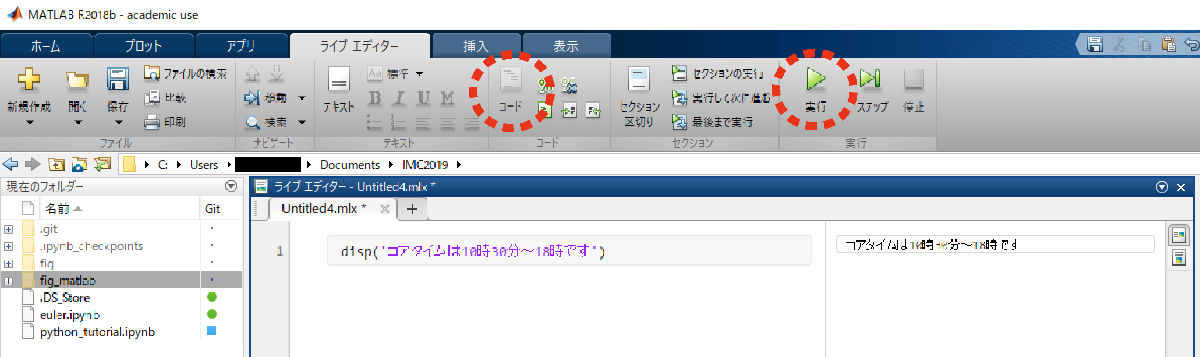

disp('コアタイムは10時30分～18時です')

コアタイムは10時30分～18時です


MALAB Live Editor の基本的な使い方は以上です．ほかの機能については以下の図か，Google先生に聞いてください．

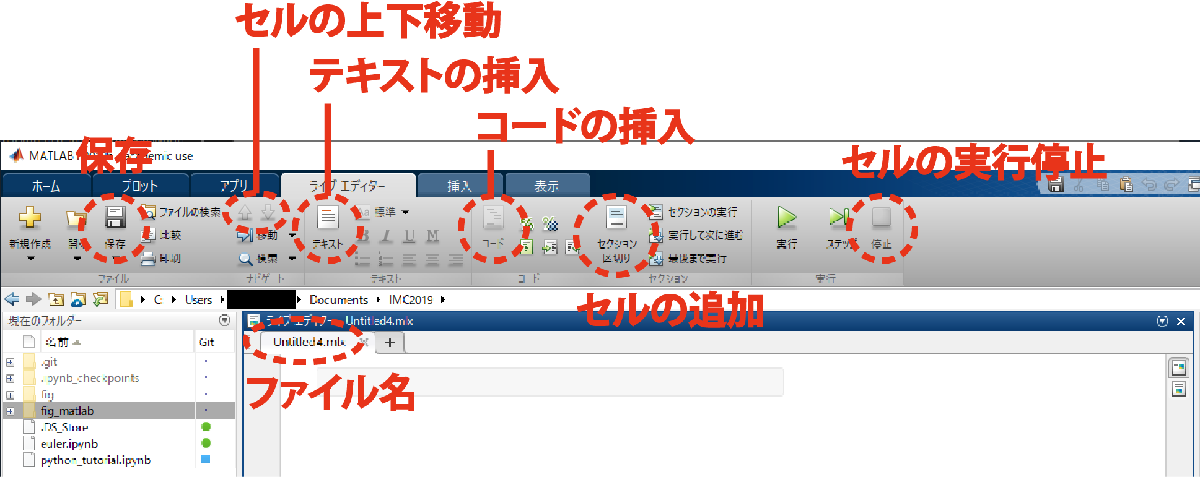

## データと計算

プログラムの主な目的はデータを加工して新しいデータを作り出すことです． 研究のプログラムでは主に次の3種類のデータを扱います．

- 数値・・・例）日付、時刻、信号、パラメータ

- 文字列・・・例）ファイル名、グラフのラベル、シミュレーションの記録

- 行列・・・例）線形代数、状態空間、座標データ

MATLABは数値と文字列を扱うことができ，また行列も扱うことができます．

以下ではそれぞれのデータについての紹介とプログラム例を示します．

### 数値

数字と記号を使って基本的な数値計算をすることができます． 試しにいくつかの数式を打ち込んで表示してみましょう．

123 + 123

ans = 246

123 - 123

ans = 0

123 * 123

ans = 15129

123 / 123

ans = 1

代入演算子「=」を使わない場合の計算結果は「ans」という変数に格納されます．「ans」に値が入っている状態で再度計算を行うと，その計算結果が「ans」に上書きされます．

1.23 + 1.23 ;
1.23 - 1.23 ;
1.23 * 1.23 ;
1.23 / 1.23 ;

MATLABでは行末にセミコロン（;）を付けると計算結果を表示しません．試しに上のサンプルの行末の「;」を消してセルを再実行してみてください．計算結果が表示されるようになります．

disp(123 + 1.23)

  124.2300



disp(123 - 1.23)

  121.7700



disp(123 * 1.23)

  151.2900



disp(123 / 1.23)

   100



計算結果のみを表示したいときは先ほどのdisp関数を使います．行末にセミコロンを入れた場合やdisp関数を使って計算結果を表示すると変数ansは使用されません．

また明示的には現れませんが，MATLABの数値には整数型（int）と浮動小数点型（float）があります．特に，後述する行列のインデックスには整数型（int）しか使うことができません．

これまでに登場した演算子（計算記号）をまとめておきます．

- + ：加算

- - ：減算

- * ：乗算

- / ：除算

計算結果は変数に代入することができます．変数はコンピュータ上のメモリ（記憶領域）に紐付けられたラベルのことで，代入はラベルと値を対応づける処理です．

次のプログラムは計算「12+30」の結果を変数「`ultimate_answer」`に代入します．

ultimate_answer = 12 + 30   % 変数に代入（%以降はコメントと呼ばれ，プログラムで処理されず無視されます．）

ultimate_answer = 42

                            % コメントはメモに便利です．

この「`=」`は等しいことを意味せず，単に変数名と値の対応を示すだけです． そのため変数に対応づける値を変えたり，変数の値を使って変数自体を更新することができます．

odyssey = 2001

odyssey = 2001


odyssey = 2010

odyssey = 2010


odyssey = odyssey + 51

odyssey = 2061


odyssey = odyssey + 940

odyssey = 3001

#### 練習問題

次の例題をやってみましょう．

- 4+3を計算し，結果を表示してください．

- $3^2$と$2^3$の和を計算し，結果を表示してください．

- 数値3を変数aに，数値2を変数bに割り当てて，これらの変数を使って問題2を解いてください．解けたら変数を変えて再計算してみてください．

% 1

% 2

% 3


### 文字列

MATLABの文字列は '文字列' あるいは "文字列" のように定義することができます．

文字列はダブルクォート「"」またはシングルクォート「'」で囲うことでデータとして扱えます．

disp("hello, world!")

hello, world!


数値と同様に，変数への代入ができます． 文字列に対しては演算子「`+」`が定義されていて，2つの文字列を結合できます．

s1 = "たけやぶやけた"

s1 = "たけやぶやけた"

s2 = 'あいうえお'

s2 = 'あいうえお'

disp(s1 + s2)

たけやぶやけたあいうえお


文字列の中に数値（例えばそれ以前に処理した計算結果）を埋め込むこともできます． これは次の例を見るほうがわかりやすいでしょう．

odyssey1 = 2001

odyssey1 = 2001

odyssey2 = 2010

odyssey2 = 2010

odyssey3 = odyssey2 + 51

odyssey3 = 2061

odyssey4 = odyssey3 + 940

odyssey4 = 3001


title1 = "An odyssey in " + odyssey1

title1 = "An odyssey in 2001"

title2 = "An odyssey in " + odyssey2

title2 = "An odyssey in 2010"

title3 = "An odyssey in " + odyssey3

title3 = "An odyssey in 2061"

title4 = "An odyssey in " + odyssey4

title4 = "An odyssey in 3001"


disp(title1)

An odyssey in 2001


disp(title2)

An odyssey in 2010


disp(title3)

An odyssey in 2061


disp(title4)

An odyssey in 3001


**練習問題**

- 変数`core_hour`と`core_minute`に制御システム研究室のコアタイムの時間，分を数値として代入し，`コアタイムはHH:MM`の形式で表示してください．

% 1


### 行列

MATLABには標準で行列を扱う機能があります．

行列計算を使ったプログラム例を示します．このプログラムは$2\times 2$行列$A,B$の内積$C$を計算します．記号を大文字にしたのは趣味です．

A = [ 1  2 ;  3  4 ]

A =      1     2
     3     4


B = [ 5  6 ;
      7  8 ]

B =      5     6
     7     8



C = A * B

C =     19    22
    43    50


1~3行目で行列A, Bを定義し，5行目で内積を計算します．

行列同士の演算は内積以外にも，

- 要素和

- 要素差

- 要素積

- 要素商

などが定義されています．

A = [ 1  2 ;
      3  4 ]

A =      1     2
     3     4


B = [ 5  6 ;
      7  8 ]

B =      5     6
     7     8


  
disp("Aの転置")

Aの転置


disp(A')

     1     3
     2     4




disp("要素和")

要素和


disp(A + B)

     6     8
    10    12




disp("要素差")

要素差


disp(A - B)

    -4    -4
    -4    -4




disp("要素積")

要素積


disp(A .* B)

     5    12
    21    32




disp("要素商")

要素商


disp(A ./ B)

    0.2000    0.3333
    0.4286    0.5000



行列の「i」列「j」行要素を取り出すには次のようにします．インデックスは1スタートです．

A = [ 1  2 ;
      3  4 ]

A =      1     2
     3     4



disp("1, 1要素")

1, 1要素


disp(A(1,1))

     1




disp("2, 1要素")

2, 1要素


disp(A(2,1))

     3



また，逆行列，行列式の計算は以下のように行います．

A = [ 1  2 ;
      3  4 ]

A =      1     2
     3     4


  
disp("逆行列")

逆行列


disp(inv(A))

   -2.0000    1.0000
    1.5000   -0.5000




disp("行列式")

行列式


disp(det(A))

    -2



#### 練習問題

        1. 次の連立方程式を逆行列を使って計算してみましょう．

            
$$\left\{ \begin{array}{r} x+3y=1 \\ 4x+5y=7 \end{array}$$


        2. 適当な2×2の正方行列に対して「inv()」の結果と逆行列の公式，

            
$$A^{-1} ={\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack }^{-1} =\frac{1}{\left|A\right|}\left\lbrack \begin{array}{cc}
d & -b\\
-c & a
\end{array}\right\rbrack$$


            の結果が一致することを確認しましょう．

% 1

% 2


**その他のデータ型**

上で挙げた数値，文字列，行列以外にもデータ型はあります．しかし研究のプログラムでは扱わない，または明示的に扱う必要がないデータので，列挙して紹介するに留めます．

- 真偽型

`       true（1）`とf`alse(0)`の2値．ブール代数（論理代数）が使える．後述する条件分岐にて説明するのでここでは省略．

## 関数

関数は一般的にあるデータを受け取り，何らかの規則で変換した結果を返すものです．MATLABで関数を作る方法はfunctionを使う方法と@を使う方法がありますが，ここでは@を使った無名関数を作る方法を説明します．無名関数は以下で定義できます．

例えば，次のセルでは受け取った値$x$の平方$\sqrt{x}$を返す関数`sqrt`を定義して，$\sqrt{2}$を計算しています．

% 目的： xの平方根を計算する
% 型： float -> float
sqrt = @(x) x^0.5

sqrt = 値をもつ function_handle :
    @(x)x^0.5



disp(sqrt(2))

    1.4142



関数を定義することの利点は可読性を維持しつつ処理を繰り返すことができる点です．処理を関数宣言の1箇所にまとめてほかの箇所で使いまわすことで，修正が必要になったとき変更すべき箇所が減ることも利点です． これらの利点はプログラムの保守性を高めます．

関数を使いまわす例を見てみましょう．次の`mid_point`はベクトル（2×1行列）で与えられた2点の中点を求める関数です．

上の関数では引数xを0.5乗したものを戻り値としています．

条件分岐や繰り返しを含む複雑な関数の作り方については後で解説します．

% 目的： 与えられたベクトルp1，p2の中点を計算する
% 型： [ double ; double ] -> [ double ; double ]
mid_point = @(p1,p2) (p1 + p2) / 2

mid_point = 値をもつ function_handle :
    @(p1,p2)(p1+p2)/2


2点間を1:3で内分する処理は次のように`mid_point`関数を再利用して構築できます．

% 目的: 与えられた2点間を1:3に内分する点を計算する
% 型： [ double ; double ] -> [ double ; double ]
divide_1_3 = @(p1,p2) mid_point(p1, mid_point(p1, p2))

divide_1_3 = 値をもつ function_handle :
    @(p1,p2)mid_point(p1,mid_point(p1,p2))



point_left = [0 ; 0] ;
point_right = [4 ; 8] ;

point_m = mid_point(point_left, point_right) ;
point_q = divide_1_3(point_left, point_right) ;

disp(point_m)

     2
     4



disp(point_q)

     1
     2



プログラムを書くときのコツとして，**関数の入力と出力が何であるか**を意識して書く方法があります． 関数を書くときは上の例のように，何を受け取り何を求めるかを示す**目的**と，受け取るデータと返すデータの**型**をコメント文で明記すべきです．

コメントを書くのは多少めんどうですが，習熟速度が段違いに変わるので**必ず**書くようにしましょう．

**練習問題**

- 受け取った数に対して，逆数をかけた数を出力する関数を書いてください．

- 三角形の3辺$a,b,c$を受け取り，角$\angle C$の余弦$\mathrm{cos}\left(\angle C\right)$を求める関数`cos_c`を書いてください．

- `cos_c`を再利用して，3辺から三角形の面積を求める関数`tri_area`を書いてください．

- `tri_area`を再利用して，3辺から三角形の内接円の半径を求める関数`rad_insc_circle`を書いてください．

% 1

% 2

% 3

% 4


## 条件分岐

ある条件を満たすときだけ処理を実行する，または満たさないとき処理を実行するためにMATLABではif文やif式を使うことができます．

条件とは真偽型の値を返す式や関数，あるいは真偽値そのものを指します．例えば「値`x`が偶数である」という条件は剰余を求める関数rem()と両辺が等しいかを判定する演算子`==`を使って次のように書くことができます．

x = 42

x = 42

condition = rem(x, 2) == 0 ;

disp(condition)

   1



値`42`は偶数なので，`condition`の値はt`rue`になっています． 奇数の場合も示します．

x = 43

x = 43


disp(rem(x, 2) == 0)

   0



こちらでは変数に代入しないで条件式の値を直接表示しました．この場合は`x`が偶数でないので，0が出力されました。

条件判定に使う`==`などの演算子はまとめて条件演算子と呼ばれます．よく使うほかの条件演算子を次に示します．

**記号 |  意味**

==     | 等号 =

~=     | 不等号 ≠

<       | 不等号 <

>       | 不等号 >

<=     | 不等号 ≤

>=     | 不等号 ≥

これらの演算子を使って処理を切り替える方法を見ていきます．

**if文**

if文は次の形式で書きます．

それぞれの処理は複数列挙できます．`elif，else`は必要なければ省略できます．if文は複数行を使って書かなければならないため，原則1行で書かなければならない無名関数の中で使うことはできません．

次のコードは`year`がうるう年かどうかに応じて出力する文字を切り替えます．if文が二重になっているため少し読みづらいですが，`year`の値を色々変えながら処理の流れを探ってみてください．

year = 2019

year = 2019


if rem(year, 400) == 0 % 西暦年が400で割り切れる年は必ずうるう年
    disp(year+"年はうるう年")
elseif rem(year, 4) == 0 % 西暦年が4で割り切れる年は（原則として）うるう年
    if rem(year, 100) == 0 % 西暦年が100で割り切れる年は（原則として）平年
        disp(year+"年は平年")
    else
        disp(year+"年はうるう年")
    end
else
    disp(year+"年は平年")
end

2019年は平年


**練習問題**

- 24時間表記の時刻`h`と`m`を受け取り，弊研究室のコアタイムに含まれるかを判定しましょう．

% 1


**if式**

if式は次の形式で書きます．

条件式を満たすときは値1、満たさないときは値2が使われます．if式はその他の計算式に埋め込むことができ，すなわち無名関数の中で使うことができます．

if式を使うとクロネッカーのデルタ，


$$\delta {\;}_{i,j} =\left\lbrace \begin{array}{cc}
1 & i=j\\
0 & \mathrm{otherwise}
\end{array}\right.$$


は次の無名関数として実装できます．

% 目的: クロネッカーのデルタ（iとjが等しいとき1、それ以外は0を返す）を実装する
% 型: (int, int) -> int
kronecker_delta = @(i, j) (i==j) * 1 + (~(i==j) * 0)

kronecker_delta = 値をもつ function_handle :
    @(i,j)(i==j)*1+(~(i==j)*0)



disp(kronecker_delta(1, 2))

     0



disp(kronecker_delta(1, 1))

     1



**練習問題**

- 2つの浮動小数`a`, `b`を受け取り大きいほうを返す`max2`関数を作りましょう．

- 3つの浮動小数`a`, `b`, `c`を受け取り最も大きいものを返す`max3`関数を作りましょう（ヒント: `max2`を再利用します）

% 1

% 2


## 繰り返し（ループ）

処理を繰り返す方法にはfor文とwhile文の2つが用意されています．C言語にあるdo-while文やgoto文はMATLABにはありません．

**for文**

MATLABのfor文はC言語のfor文とは異なる動作をします．MATLABのforはイテレータ（配列やここでは説明していないリスト型など）の各要素に対して処理を行うときに使われます．

整数`0`から`9`までを順番に画面表示するコードを示します．

for i=0:9
    disp(i)
end

     0

     1

     2

     3

     4

     5

     6

     7

     8

     9



ここで1:10は配列（1×10行列）`[0  1 ..., 9]`を返す関数です． つまりこの処理は行列（ベクトル）の要素である`0`, `1`, ..., `9`を順番に変数`i`に束縛し，それぞれの`i`に関してdisp関数を呼び出しています．

このイテレータは連番である必要はなく，例えば次のような**行**ベクトル`v`にもfor文を適用できます．

v = [3.14  42.0  1701.0]

v = 	1.0e+03 *

    0.0031    0.0420    1.7010



for f = v
    disp(f * 10.0)
end

   31.4000

   420

       17010



for文は二重，三重にできます．

for i=1:3
    for j=1:3
        disp(i + j)
    end
end

     2

     3

     4

     3

     4

     5

     4

     5

     6



**練習問題**

- 1から100までの数字を合計して表示しましょう．

- for文を二重に使って，各インデックスの組に対して`kronecker_delta(i, j)`を計算して表示してみましょう．

% 1

% 2


**while文**

while文の働きはC言語のものとよく似ています．括弧がない点を除くと文法も同じなので，ここでは使用例だけ示します．for文の練習問題1はwhile文を使うと次のように書けます．

total = 0

total = 0

i = 1

i = 1

while i<=100
    total = total + i ;
    i = i + 1 ;
end
disp(total)

        5050



ただしfor文を使うほうがスッキリするので普通はやりません．

while文を使うのは終了条件を満たすまで処理を繰り返したいときです．次の例は[ニュートン法](https://ja.wikipedia.org/wiki/%E3%83%8B%E3%83%A5%E3%83%BC%E3%83%88%E3%83%B3%E6%B3%95)というアルゴリズムを使って方程式$x^2 -42=0$の解，すなわち$\sqrt{42}$を計算しています． 解の更新量`update`がしきい値$1\times {10}^{-10}$を下回るまで更新を繰り返します．

f = @(x) x^2 - 42

f = 値をもつ function_handle :
    @(x)x^2-42


df = @(x) 2*x

df = 値をもつ function_handle :
    @(x)2*x



x = 3.14

x = 3.1400

update = f(x)/df(x)

update = -5.1179


while abs(update) > 1E-10
    x = x - update;
    update = f(x)/df(x);
end

disp(x)

    6.4807



**練習問題**

- 300,000を超える最小のフィボナッチ数を計算しましょう．

% 1


## 研究で使う関数、テクニック

以上がMATLABの基礎でした．説明していないものもたくさんありますが，それは必要となったときに各自で調べるようにしてください．特にMATLABの開発元である[MathWorksのページ](https://jp.mathworks.com/)には非常に詳しい日本語のヘルプや関数の使い方などが充実しています．また検索エンジンで「matlab  （やりたいこと）」で調べるとだいたい欲しい情報が載っているページにたどり着けます．

ここからは研究で使う関数やテクニックを紹介します．特にグラフを作ることは必須ですので使い方を覚えましょう．

**もっとMATLAB**

MATLABで個人的によく使う関数を紹介します．数が多いので説明はコメントにて簡単に述べるに留めます．

linspace(0,1,3)% 範囲を線形に分割したベクトル

ans =          0    0.5000    1.0000


zeros(4, 1) % 指定サイズのゼロベクトルまたは行列

ans =      0
     0
     0
     0


ones(2, 3) % すべてが1のベクトルまたは行列

ans =      1     1     1
     1     1     1


eye(3) % 指定サイズの単位行列

ans =      1     0     0
     0     1     0
     0     0     1



A = [1  2  3 ; 3  4  5 ;  5  6  7 ; 7  8  9 ]

A =      1     2     3
     3     4     5
     5     6     7
     7     8     9


A(1,:) % 行列の特定行を抜き出す

ans =      1     2     3


A(:,1) % 行列の特定列を抜き出す

ans =      1
     3
     5
     7


A(2:3,1) % 行列の一部を抜き出す

ans =      3
     5


A(:,1:2) % 行列の一部を抜き出す

ans =      1     2
     3     4
     5     6
     7     8


**2次元グラフ関数plot**

`plot`関数でグラフを描画し画面に表示します．

% 0~2piの範囲のsin(x)を計算する
sine = 12*sin(linspace(0,2*pi,200))

sine =          0    0.3788    0.7573    1.1350    1.5115    1.8866    2.2597    2.6307    2.9990    3.3643    3.7262    4.0845    4.4386    4.7884    5.1333    5.4732    5.8076    6.1362    6.4587    6.7747    7.0840    7.3863    7.6812    7.9684    8.2476    8.5187    8.7813    9.0351    9.2799    9.5154    9.7415    9.9579   10.1643   10.3606   10.5466   10.7220   10.8868   11.0407   11.1836   11.3154   11.4359   11.5450   11.6425   11.7285   11.8028   11.8653   11.9160   11.9548   11.9817   11.9966


cose = 9*cos(linspace(0,2*pi,200))

cose =     9.0000    8.9955    8.9821    8.9597    8.9283    8.8881    8.8390    8.7811    8.7144    8.6391    8.5551    8.4626    8.3617    8.2524    8.1350    8.0094    7.8758    7.7344    7.5852    7.4285    7.2644    7.0931    6.9147    6.7293    6.5373    6.3388    6.1339    5.9230    5.7061    5.4835    5.2555    5.0223    4.7840    4.5410    4.2934    4.0415    3.7857    3.5260    3.2629    2.9964    2.7270    2.4549    2.1804    1.9036    1.6250    1.3447    1.0631    0.7805    0.4970    0.2131


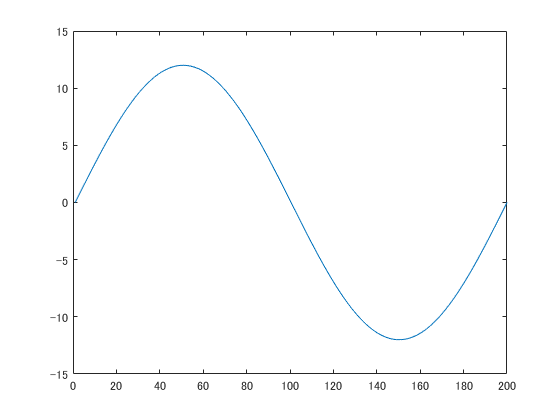


% `sine`と`cose`を線グラフにして表示
plot(sine)

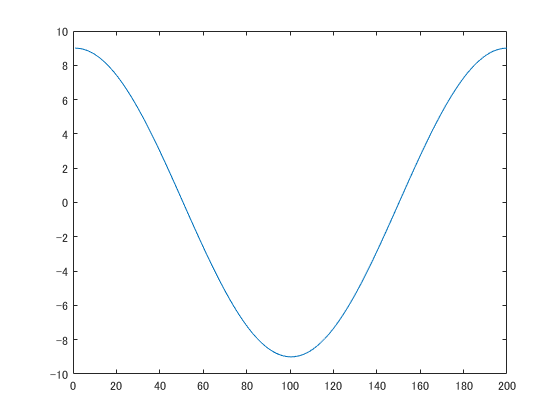

plot(cose)

`plot関数の後にlegend`を与えることで，線に名前をつけられます．

% 横軸
time = linspace(0, 2*pi, 200)

time =          0    0.0316    0.0631    0.0947    0.1263    0.1579    0.1894    0.2210    0.2526    0.2842    0.3157    0.3473    0.3789    0.4105    0.4420    0.4736    0.5052    0.5368    0.5683    0.5999    0.6315    0.6630    0.6946    0.7262    0.7578    0.7893    0.8209    0.8525    0.8841    0.9156    0.9472    0.9788    1.0104    1.0419    1.0735    1.1051    1.1367    1.1682    1.1998    1.2314    1.2630    1.2945    1.3261    1.3577    1.3892    1.4208    1.4524    1.4840    1.5155    1.5471



% 0~2piの範囲のsin(x)を計算する
sine = 12*sin(time)

sine =          0    0.3788    0.7573    1.1350    1.5115    1.8866    2.2597    2.6307    2.9990    3.3643    3.7262    4.0845    4.4386    4.7884    5.1333    5.4732    5.8076    6.1362    6.4587    6.7747    7.0840    7.3863    7.6812    7.9684    8.2476    8.5187    8.7813    9.0351    9.2799    9.5154    9.7415    9.9579   10.1643   10.3606   10.5466   10.7220   10.8868   11.0407   11.1836   11.3154   11.4359   11.5450   11.6425   11.7285   11.8028   11.8653   11.9160   11.9548   11.9817   11.9966


cose = 9*cos(time)

cose =     9.0000    8.9955    8.9821    8.9597    8.9283    8.8881    8.8390    8.7811    8.7144    8.6391    8.5551    8.4626    8.3617    8.2524    8.1350    8.0094    7.8758    7.7344    7.5852    7.4285    7.2644    7.0931    6.9147    6.7293    6.5373    6.3388    6.1339    5.9230    5.7061    5.4835    5.2555    5.0223    4.7840    4.5410    4.2934    4.0415    3.7857    3.5260    3.2629    2.9964    2.7270    2.4549    2.1804    1.9036    1.6250    1.3447    1.0631    0.7805    0.4970    0.2131


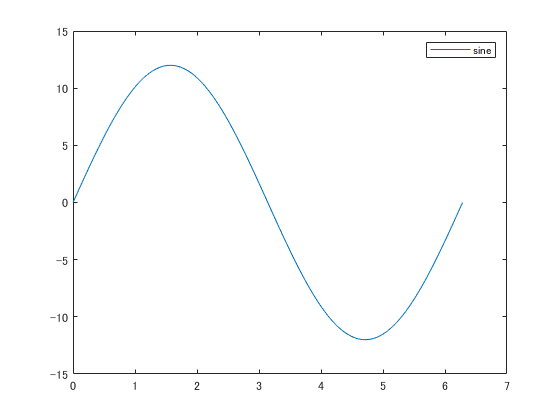


% `sine`を線グラフにして表示
plot(time, sine)
legend sine % ラベルをつける

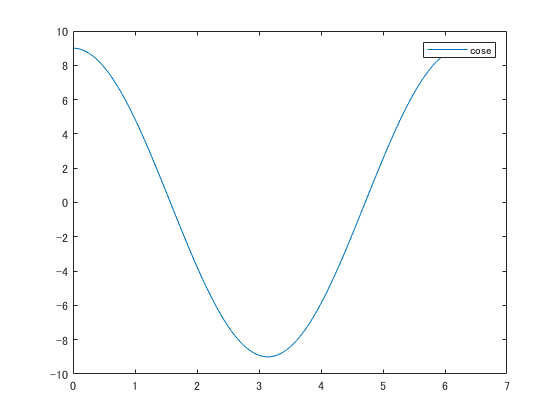


% `cose`を線グラフにして表示
plot(time, cose)
legend cose % ラベルをつける

軸ラベルは`xlabel`, `ylabel`でつけられます．

% 横軸
time = linspace(0, 2*pi, 200)

time =          0    0.0316    0.0631    0.0947    0.1263    0.1579    0.1894    0.2210    0.2526    0.2842    0.3157    0.3473    0.3789    0.4105    0.4420    0.4736    0.5052    0.5368    0.5683    0.5999    0.6315    0.6630    0.6946    0.7262    0.7578    0.7893    0.8209    0.8525    0.8841    0.9156    0.9472    0.9788    1.0104    1.0419    1.0735    1.1051    1.1367    1.1682    1.1998    1.2314    1.2630    1.2945    1.3261    1.3577    1.3892    1.4208    1.4524    1.4840    1.5155    1.5471



% 0~2piの範囲のsin(x)を計算する
sine = 12*sin(time)

sine =          0    0.3788    0.7573    1.1350    1.5115    1.8866    2.2597    2.6307    2.9990    3.3643    3.7262    4.0845    4.4386    4.7884    5.1333    5.4732    5.8076    6.1362    6.4587    6.7747    7.0840    7.3863    7.6812    7.9684    8.2476    8.5187    8.7813    9.0351    9.2799    9.5154    9.7415    9.9579   10.1643   10.3606   10.5466   10.7220   10.8868   11.0407   11.1836   11.3154   11.4359   11.5450   11.6425   11.7285   11.8028   11.8653   11.9160   11.9548   11.9817   11.9966


cose = 9*cos(time)

cose =     9.0000    8.9955    8.9821    8.9597    8.9283    8.8881    8.8390    8.7811    8.7144    8.6391    8.5551    8.4626    8.3617    8.2524    8.1350    8.0094    7.8758    7.7344    7.5852    7.4285    7.2644    7.0931    6.9147    6.7293    6.5373    6.3388    6.1339    5.9230    5.7061    5.4835    5.2555    5.0223    4.7840    4.5410    4.2934    4.0415    3.7857    3.5260    3.2629    2.9964    2.7270    2.4549    2.1804    1.9036    1.6250    1.3447    1.0631    0.7805    0.4970    0.2131


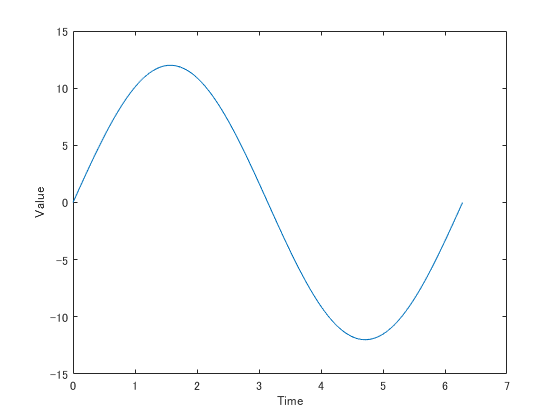


% `sine`を線グラフにして表示
plot(time, sine)
xlabel("Time")
ylabel("Value")

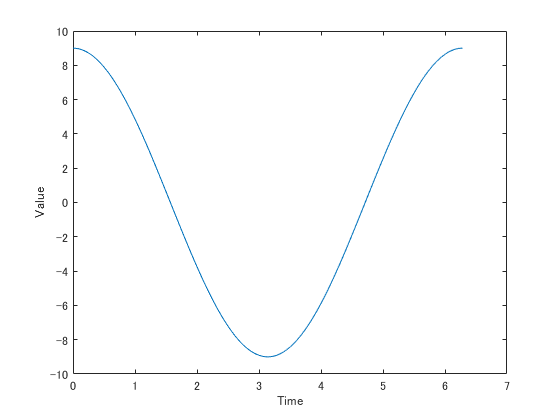


% `cose`を線グラフにして表示
plot(time, cose)
xlabel("Time")
ylabel("Value")

また，hold を使うことで複数のグラフを重ねて表示できます．

% 横軸
time = linspace(0, 2*pi, 200)

time =          0    0.0316    0.0631    0.0947    0.1263    0.1579    0.1894    0.2210    0.2526    0.2842    0.3157    0.3473    0.3789    0.4105    0.4420    0.4736    0.5052    0.5368    0.5683    0.5999    0.6315    0.6630    0.6946    0.7262    0.7578    0.7893    0.8209    0.8525    0.8841    0.9156    0.9472    0.9788    1.0104    1.0419    1.0735    1.1051    1.1367    1.1682    1.1998    1.2314    1.2630    1.2945    1.3261    1.3577    1.3892    1.4208    1.4524    1.4840    1.5155    1.5471



% 0~2piの範囲のsin(x)を計算する
sine = 12*sin(time)

sine =          0    0.3788    0.7573    1.1350    1.5115    1.8866    2.2597    2.6307    2.9990    3.3643    3.7262    4.0845    4.4386    4.7884    5.1333    5.4732    5.8076    6.1362    6.4587    6.7747    7.0840    7.3863    7.6812    7.9684    8.2476    8.5187    8.7813    9.0351    9.2799    9.5154    9.7415    9.9579   10.1643   10.3606   10.5466   10.7220   10.8868   11.0407   11.1836   11.3154   11.4359   11.5450   11.6425   11.7285   11.8028   11.8653   11.9160   11.9548   11.9817   11.9966


cose = 9*cos(time)

cose =     9.0000    8.9955    8.9821    8.9597    8.9283    8.8881    8.8390    8.7811    8.7144    8.6391    8.5551    8.4626    8.3617    8.2524    8.1350    8.0094    7.8758    7.7344    7.5852    7.4285    7.2644    7.0931    6.9147    6.7293    6.5373    6.3388    6.1339    5.9230    5.7061    5.4835    5.2555    5.0223    4.7840    4.5410    4.2934    4.0415    3.7857    3.5260    3.2629    2.9964    2.7270    2.4549    2.1804    1.9036    1.6250    1.3447    1.0631    0.7805    0.4970    0.2131


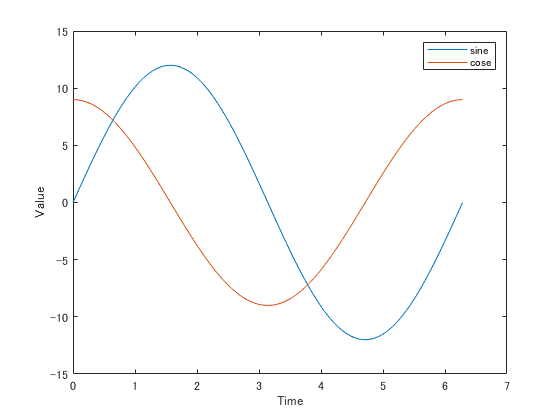


% `sine`を線グラフにして表示
plot(time, sine)
hold on % グラフをホールドする
% `cose`を線グラフにして重ねて表示
plot(time, cose)
hold off % ホールド解除

legend sine cose
xlabel("Time")
ylabel("Value")